# FastCormics (Senescence)

% add all subfolders to path
addpath(genpath(pwd))

% load the data
gxData = readtable('NEW_SenescenceGEM_ControlSen_NoFilter_geneExpressionData.txt');
senescenceData= gxData(:,[1,2,3,5])

senescenceData = 19855×4 table
      Ensembl_GeneID          HGNC_ID        HGNC_GeneSymbol    Senescent_GeneExpression_Level
    ___________________    ______________    _______________    ______________________________

    {'ENSG00000089127'}    {'HGNC:8086' }     {'OAS1'     }                 8.9128            
    {'ENSG00000126709'}    {'HGNC:4054' }     {'IFI6'     }                 527.39            
    {'ENSG00000162692'}    {'HGNC:12663'}     {'VCAM1'    }                 25.489            
    {'ENSG00000104043'}    {'HGNC:13536'}     {'ATP8B4'   }                 1.6619            
    {'ENSG00000167900'}    {'HGNC:11830'}     {'TK1'      }                 1.4123            
    {'ENSG00000118971'}    {'HGNC:1583' }     {'CCND2'    }                 20.755            
    {'ENSG00000111335'}    {'HGNC:8087' }     {'OAS2'     }             

colnames = {'SenescentCell'}

colnames = 1×1 cell array
    {'SenescentCell'}


rownames = table2cell(senescenceData(:,2))

rownames = 19855×1 cell array
    {'HGNC:8086' }
    {'HGNC:4054' }
    {'HGNC:12663'}
    {'HGNC:13536'}
    {'HGNC:11830'}
    {'HGNC:1583' }
    {'HGNC:8087' }
    {'HGNC:1933' }
    {'HGNC:2640' }
    {'HGNC:10618'}
    {'HGNC:4832' }
    {'HGNC:4831' }
    {'HGNC:17111'}
    {'HGNC:53015'}
    {'HGNC:5208' }
    {'HGNC:26072'}
    {'HGNC:4719' }
    {'HGNC:2016' }
    {'HGNC:33747'}
    {'HGNC:2351' }
    {'HGNC:28087'}
    {'HGNC:4555' }
    {'HGNC:9341' }
    {'HGNC:9998' }
    {'HGNC:44112'}
    {'HGNC:21345'}
    {'HGNC:11932'}
    {'HGNC:1723' }
    {'HGNC:1318' }
    {'HGNC:1857' }



% set figure flag: 1 to output and save density plot
figflag = 1;

# Data discretization

## log2-transform the data

% log2-transform the data
signal = log2(table2array(senescenceData(:,4)));

% transform all -Inf to -10000
signal(isinf(signal)) = -10000;

% for each sample
for j = 1:size(colnames,2)
    signal_sample = signal(:,j); % save only current sample
    data_keep = senescenceData(:,j);
    signal_sample = signal_sample(signal_sample>-10000); % remove samples with low expression
end

# Density Plot

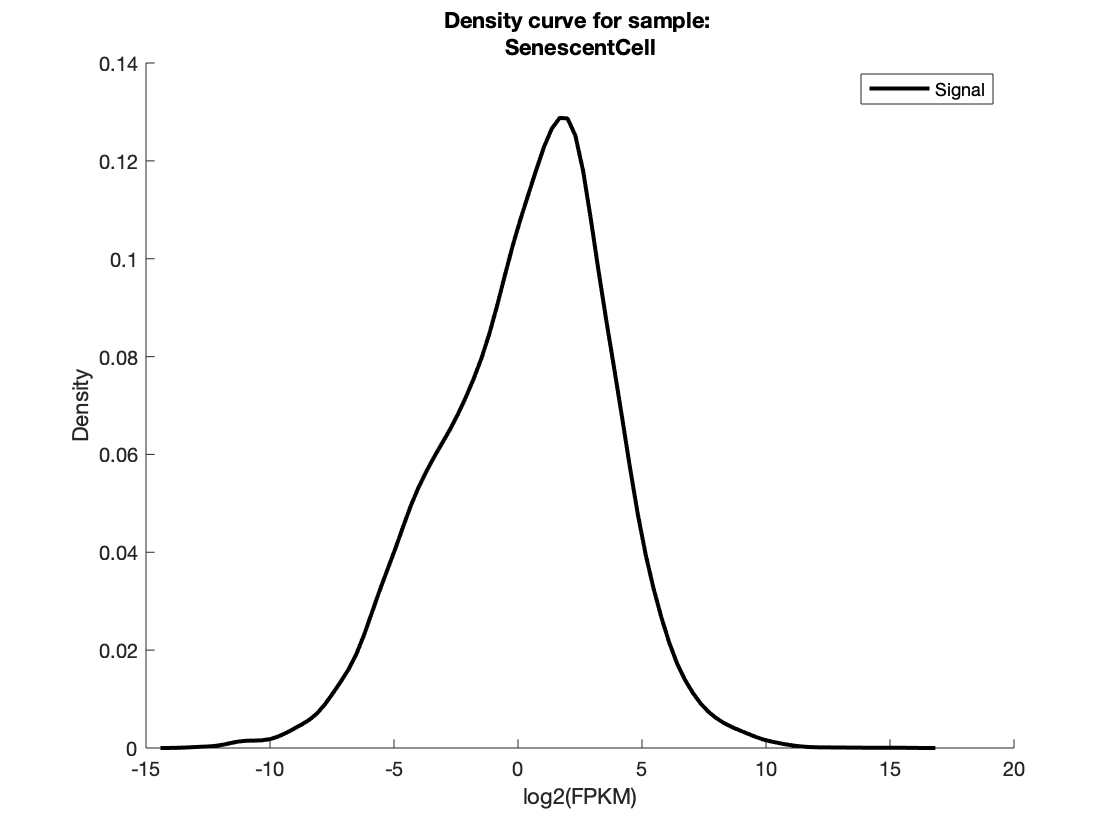

[probability_estimate,xi] = ksdensity((signal_sample)); % get the densities
    
    if figflag;
        figure; hold on
        plot(xi,probability_estimate,'-k','LineWidth',2);
        title({'Density curve for sample: ', colnames{1,j}});
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal'},'Location','best');end

# Create

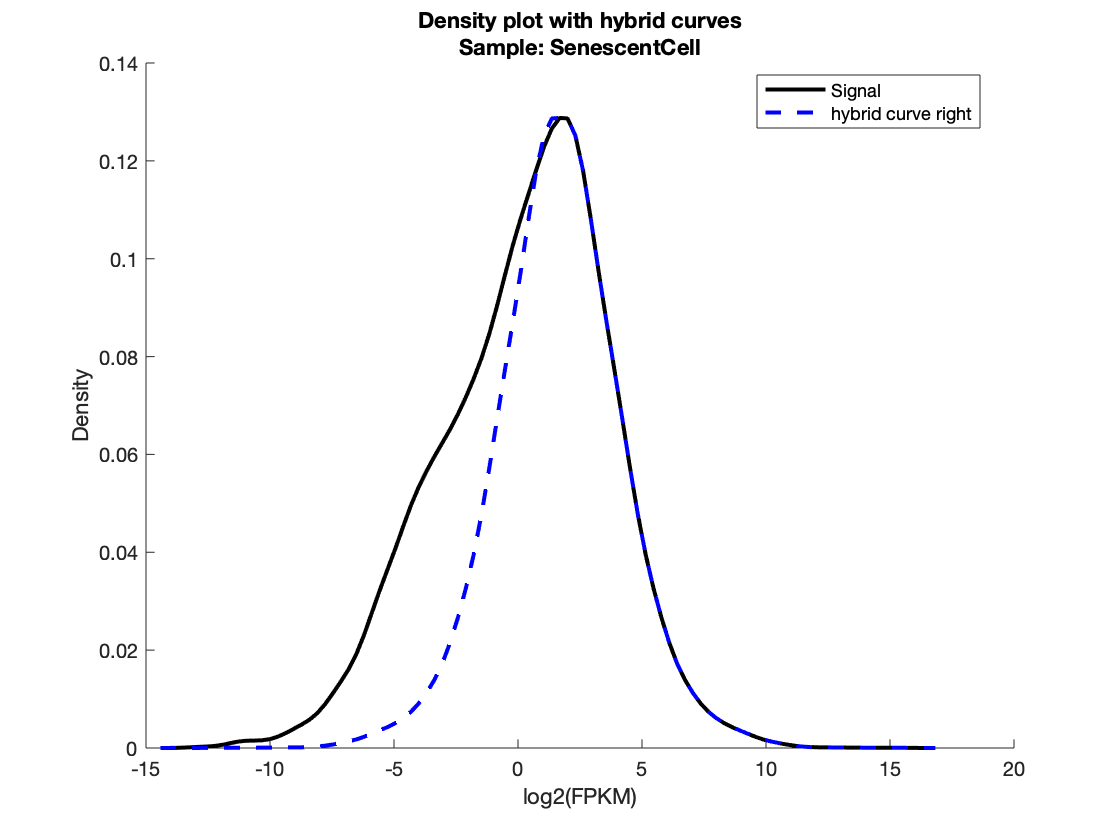

% find the maximum of the density curve
peak_max_idx = (find(probability_estimate==max(probability_estimate)));

% copy right-most side of density curve
max_r_side = probability_estimate(peak_max_idx:end);

% mirror the right side
max_l_side = flip(max_r_side);
hybrid = [max_l_side(1:end-1), max_r_side];


% create hybrid curve
hybrid_curve = zeros(numel(probability_estimate),1);

if numel(hybrid)> numel(probability_estimate)
        hybrid_curve(end+1-numel(hybrid(end-100+1:end)):end)=hybrid(end-100+1:end);
        x = zeros(numel(probability_estimate),1); % create new x-axis
    else
        hybrid_curve(end-numel(hybrid)+1:end) = hybrid;
        x = xi;
    end

 if figflag
        plot(x,hybrid_curve,'b--','LineWidth',2);
        legend({'Signal','hybrid curve right'});
        title({'Density plot with hybrid curves',['Sample: ', colnames{1,j}]},'interpreter','none');end

    
clear peak_max_idx max_l_side max_r_side hybrid

# Create Left Curve (main, right most curve)

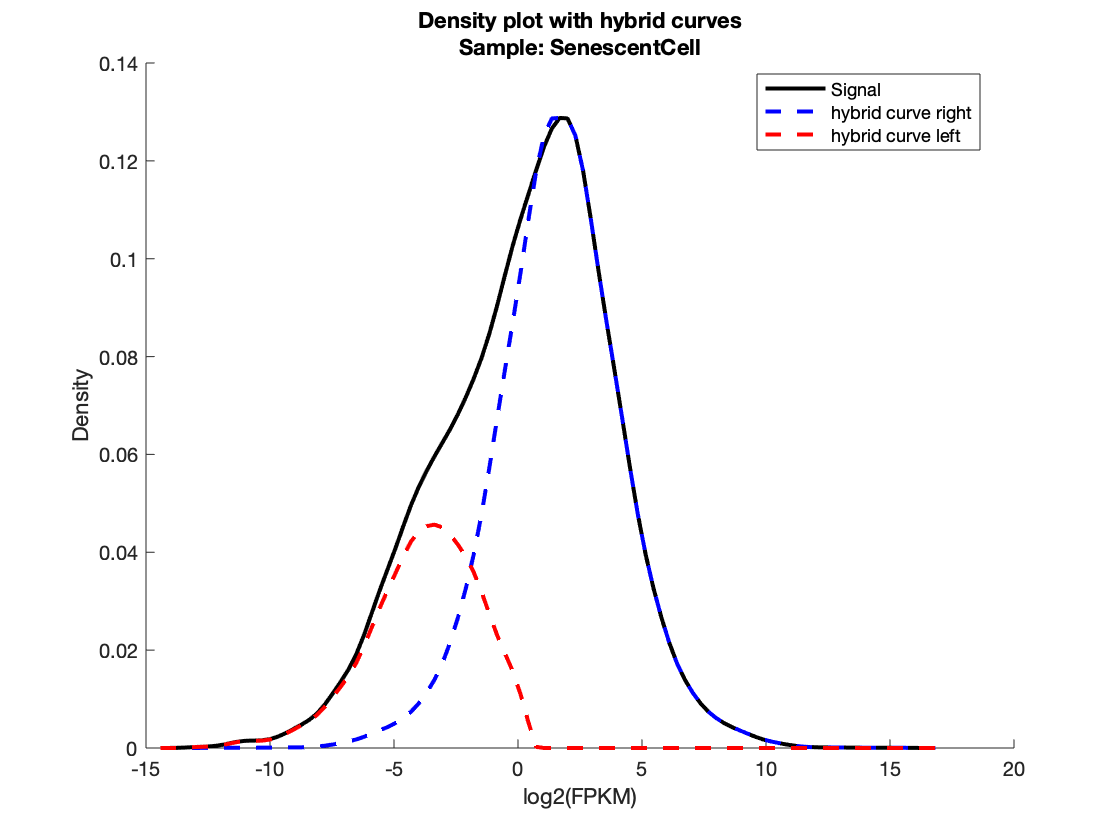

 rest_curve = probability_estimate - hybrid_curve';
    rest_curve(find(rest_curve<0.0001))=0;
        if figflag;
        plot(xi,rest_curve, 'r--','LineWidth',2);
        legend({'Signal','hybrid curve right','hybrid curve left'});end

# Fit of Curves

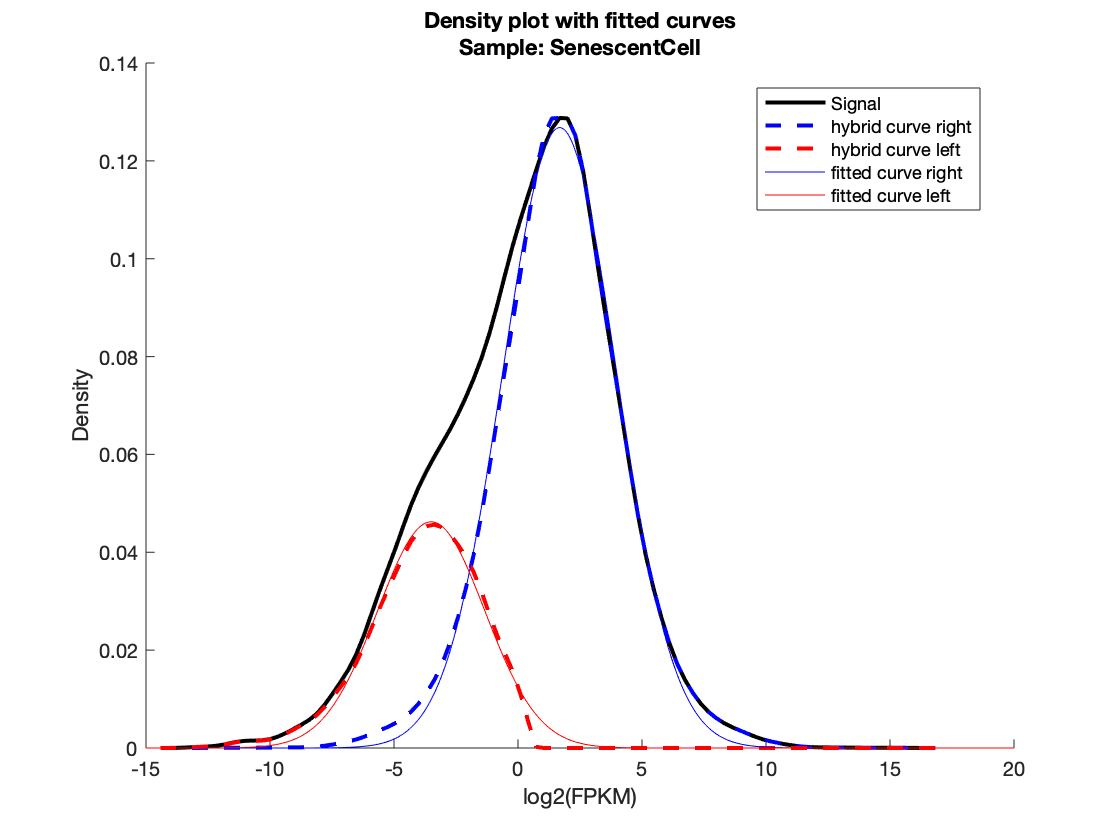

[fitresult_r, ~] = createFit_r(xi, hybrid_curve); % right curve
    [fitresult_l, ~] = createFit_l(xi, rest_curve); % left curve
    
    if figflag;
        plot(fitresult_r,'b');
        plot(fitresult_l),'g';
        title({'Density plot with fitted curves',['Sample: ', colnames{1,j}]},'interpreter','none');
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal', 'hybrid curve right', 'hybrid curve left','fitted curve right','fitted curve left'});
  %  saveas(gcf,['Figures\density_', colnames{1,j},'.png']);
    end

#  zFRMA transforms the data and plot the density

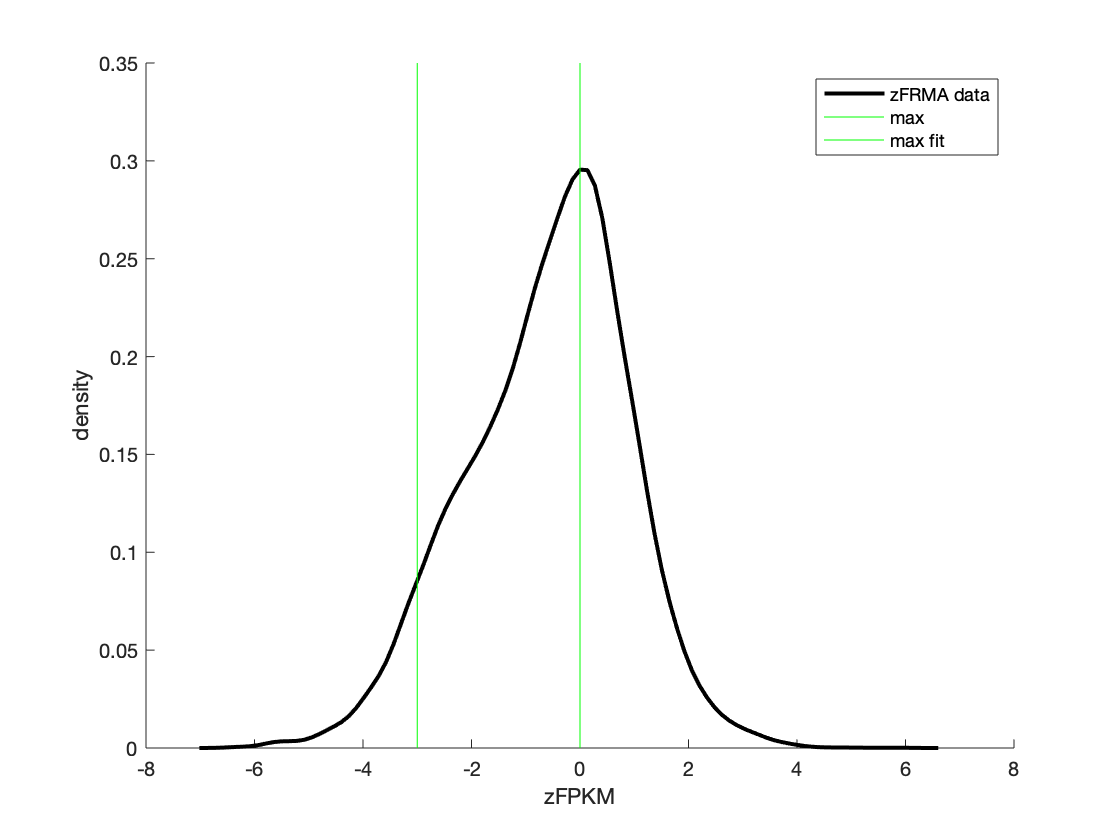

sigma1 = fitresult_r.c1/sqrt(2);
mu1 = fitresult_r.b1; % x-value of right max
    
zFRMA = (signal_sample-mu1)/sigma1;
[yFRMA,xFRMA] = ksdensity(zFRMA);
    
    if figflag; figure;hold on;
        plot(xFRMA,yFRMA,'-k','LineWidth',2);
        xlabel('zFPKM');
        ylabel('density');
        line([0 0], [0.0 0.35],'color', [0,1,0])
        line([-3 -3], [0.0 0.35],'color', [0,1,0]);
        legend({'zFRMA data','max','max fit'});end

    
clear hybrid_curve probability_estimate rest_curve yFRMA xFRMA x xi ans

# Discretization


    zFRMA = (signal(:,j)-mu1)/sigma1; % calculate zFRMA
     
    sigma2 = fitresult_l.c1/sqrt(2);
    mu2 = fitresult_l.b1; % x-value of left max
    mu2_t=(mu2-mu1)/sigma1;
    
    discretized = zFRMA;
    
    e = 0;
    ue = max(-3, mu2_t);
    zFRMA = reshape(zFRMA,size(data_keep,1),size(data_keep,2));
    
    exp_threshold = e;
    unexp_threshold = ue;
    exp=find(discretized>=exp_threshold);
    not_exp=find(discretized<=unexp_threshold);
    unknown = find(discretized<exp_threshold & discretized>unexp_threshold);
    
    discretized(unknown)    = 0;    % unknown expression is set to 0
    discretized(not_exp)    = -1;   % non-expression is set to -1
    discretized(exp)        = 1;    % expression is set to 1
    
    discretized = (reshape(discretized,size(data_keep,1),size(data_keep,2)));
    discretized_keep(j,:) = discretized'; % save for each sample
    
    clear fitresult_l fitresult_r data_keep e exp exp_threshold mu1 mu2 mu2_t not_exp sigma1 sigma2 signal2 signal_sample ue unexp_threshold unknown zFRMA

discretized=discretized_keep';
clear j discretized_keep signal
%close all



# FastCormics with Medium and Models 

load cRecon204.mat  % consistent Recon 2.04 model, obtained by running FASTCC (Vlassis et al., 2014)
load medium_example % need to define medium for the cells used here
load dico_ML.mat % dictionary to map the rownname identifier to the genes in the model

Cmodel.genes = regexprep(Cmodel.genes,'\.[0-9]+$',''); %removal of gene transcripts

consensus_proportion = 0.9; %gene has to be expressed in 90% of the cases in order to be included. Only relevant if you want to create one generic model from different samples

# Set optional settings  (Example) (NOT WORKING)

% unpenalized = Cmodel.rxns(ismember(Cmodel.subSystems,unpenalizedSystems));
% optional_settings.unpenalized = unpenalized;
% 
% optional_settings.func = {'DM_atp_c_';'biomass_reaction'}; % forced reactions
% 
% not_medium_constrained = 'EX_tag_hs(e)';
% optional_settings.not_medium_constrained = not_medium_constrained;
% 
% optional_settings.medium = medium_example;% remove field if no constraint is provided

# single models:

epsilon = 1e-6

epsilon = 1.0000e-06

for i = 1:numel(colnames) %for each sample
    [model_out{i}, A_keep{i}] = fastcormics_2018(Cmodel, discretized(:,i), ...
        rownames, dico , 0, consensus_proportion, epsilon);
end

Error using cell/intersect>cellintersectR2012a (line 280)
Input A of class double and input B of class cell must be cell arrays of character vectors, unless one is a character vector.

Error in cell/intersect (line 84)
    [varargout{1:nlhs}] = cellintersectR2012a(varargin{:}); 

Error in 

# generic models:

[model_out_generic, A_keep_generic] = fastcormics_2018(Cmodel, discretized, ...
    rownames, dico , 0, consensus_proportion, epsilon, optional_settings);